TS5

P1

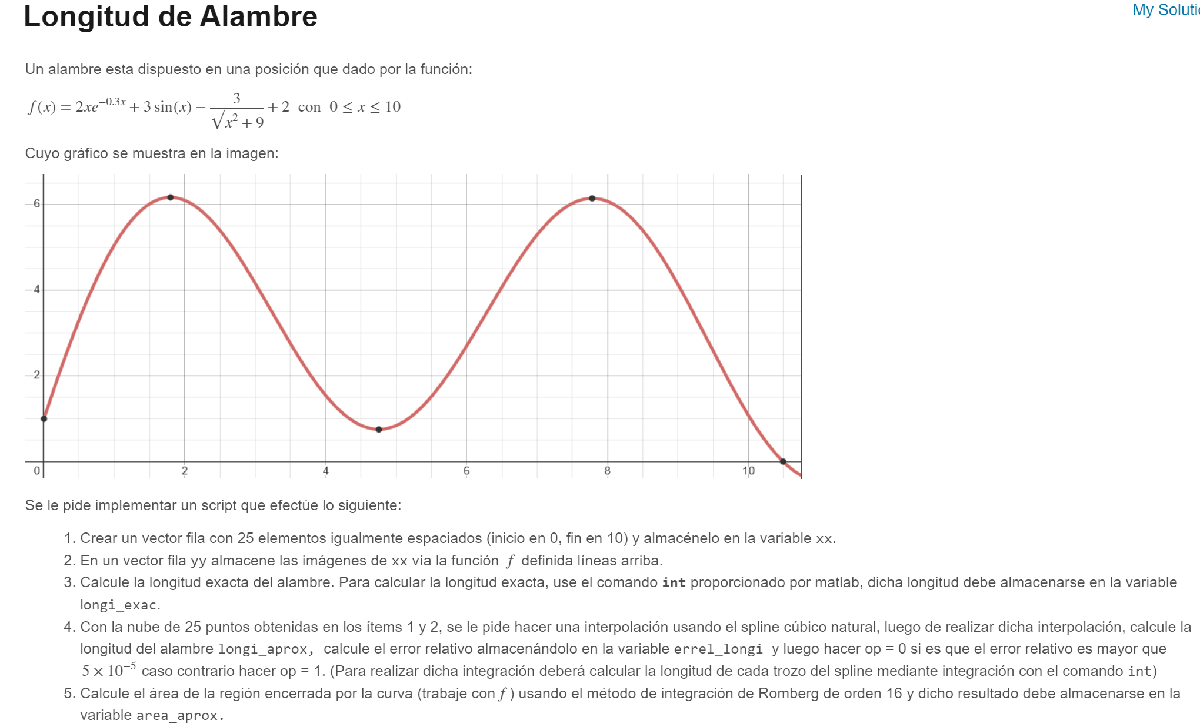

format long 

% Define la variable simbólica x
syms x 

% Define la función f(x) como una combinación de términos exponenciales, trigonométricos y racionales
f= 2*x*exp(-0.3*x) + 3*sin(x) - (3/sqrt(x^2 + 9)) + 2; 

% Calcula la derivada simbólica de la función f con respecto a x
g = diff(f, x);

% Calcula la función sqrt(1 + g^2), que es parte de la fórmula de la longitud de arco
h = sqrt(1 + g^2);

% Calcula la longitud de arco exacta de f(x) en el intervalo [0,10] usando integración simbólica y la convierte a número de punto flotante
longi_exac = double(int(h, 0, 10));

% Genera 25 puntos equidistantes en el intervalo [0,10]
xx = linspace(0, 10, 25);

% Evalúa la función f en los puntos xx
yy = double(subs(f, x, xx))

yy =    1.000000000000000   2.959065502992785   4.555013955077179   5.642100131967266   6.133835462842535   6.023395560812960   5.389027916419567   4.383802838005512   3.211860987560710   2.095514501406167   1.238977426273322   0.794985504354147   0.840033022067356   1.362471676429293   2.265517942092534   3.384668368334164   4.516559457539697   5.454351327255603   6.023597622398078   6.112479736435884   5.691246166409656   4.817543285037654   3.626736332364564   2.308886273379980   1.076330149122824



% Calcula el spline natural de los puntos (xx, yy)
spline_f = splinenatural(xx, yy);

% Inicializa la variable para la longitud aproximada del arco
longitud = 0; 

% Bucle para calcular la longitud aproximada del arco sumando segmentos del spline

for i = 1:length(xx)-1
    
    c = spline_f(i, :);
    
    syms t
    
    spline_t = c(1)*t^3 + c(2)*t^2 + c(3)*t + c(4);
    
    dspline_dt = diff(spline_t, t);
    
    sub_longi = double(int(sqrt(1 + dspline_dt^2), 0, xx(i+1)-xx(i)));
    
    longitud = longitud + sub_longi;
end

% Guarda la longitud aproximada calculada con splines

longi_aprox = longitud

longi_aprox =   24.002911882259102



% Calcula el error relativo entre la longitud exacta y la aproximada
errel_longi = abs(longi_exac - longi_aprox) / longi_exac

errel_longi =      3.374432200737474e-05



% Comprueba si el error relativo es menor que un umbral
if errel_longi > 5e-5 
    op = 0; % Si el error es grande, asigna 0 a op
else
    op = 1; % Si el error es aceptable, asigna 1 a op
end

fun=matlabFunction(f);

% Calcula la integración de f(x) en [0,10] usando el método de Romberg con orden 16
[T, R] = romberg(fun, 0, 10, 16); 

% Guarda el resultado de la integración con Romberg como área aproximada
area_aprox = R

area_aprox =   37.557230204901501



%{
function S = splinenatural(X,Y)
    N=length(X)-1; H=diff(X); E=diff(Y)./H;
    diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1);
    g0=0; gn=0;
    A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b=6*diff(E'); g=A\b;
    g=[g0 g' gn];
    figure(7); clf;
    for i=1:N
        S(i,1)=(g(i+1)-g(i))/(6*H(i));
        S(i,2)=g(i)/2;
        S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4)=Y(i);
        xx=linspace(X(i),X(i+1),100);
        yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy,'LineWidth',2), hold on
    end
    plot(X,Y,'or','MarkerSize',10,'LineWidth',2);
    grid on, hold off
end

% Método de Romberg para integración numérica

function [T, R] = romberg(fun, a, b, orden)
    interv = 1; 
    
    % Calcula la tabla de integración compuesta
    for j = 1:orden
        T(j,1) = Tcomp(fun, a, b, interv); 
        interv = interv * 2; 
    end
    
    % Aplicación del esquema de extrapolación de Romberg
    for k = 2:orden
        for j = 1:(orden - k + 1)
            T(j,k) = (4^(k-1) * T(j+1,k-1) - T(j,k-1)) / (4^(k-1) - 1); 
        end
    end

    % La mejor aproximación está en la esquina superior derecha de la tabla
    R = T(1,orden); 
end

% Método de integración compuesta de trapecios
function [Itrapcomp] = Tcomp(f, a, b, n)
    h = (b - a) / n; % Longitud de cada subintervalo
    x = [a:h:b]; % Puntos de la partición
    
    % Aplicación de la regla del trapecio compuesta
    Itrapcomp = (h / 2) * (f(a) + 2 * sum(f(x(2:end-1))) + f(b)); 
end
%}

P2

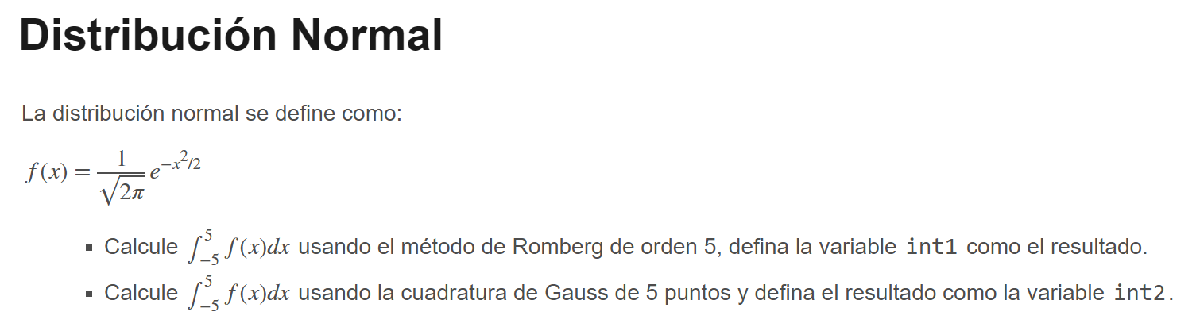

f = @(x) 1/(sqrt(2*pi))*exp(-x.^(2)/2)
[t,r] = romberg(f,-5,5,5)
int1 = r
int2 = QuadraturaGauss(f,-5,5,5)


P3

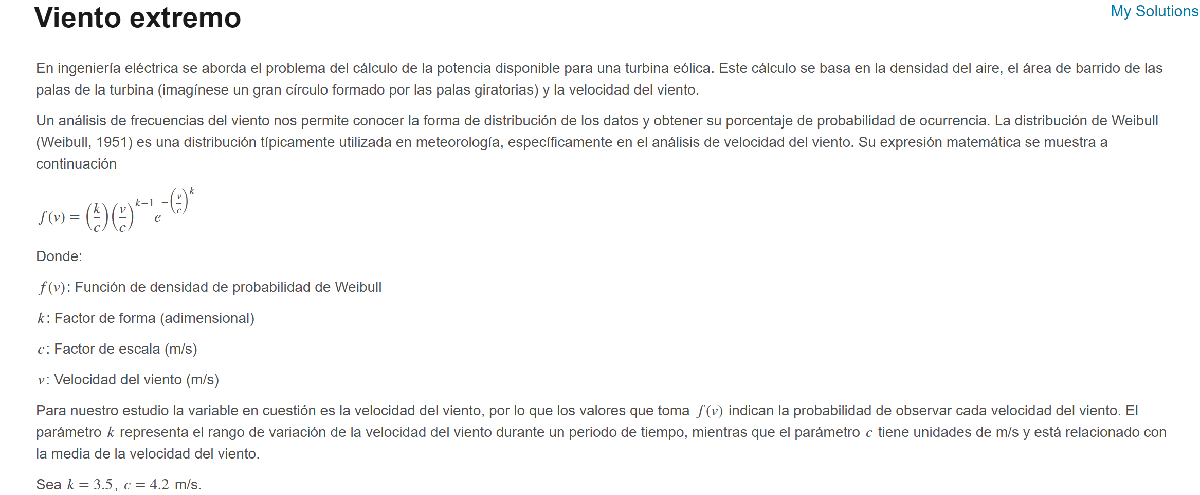

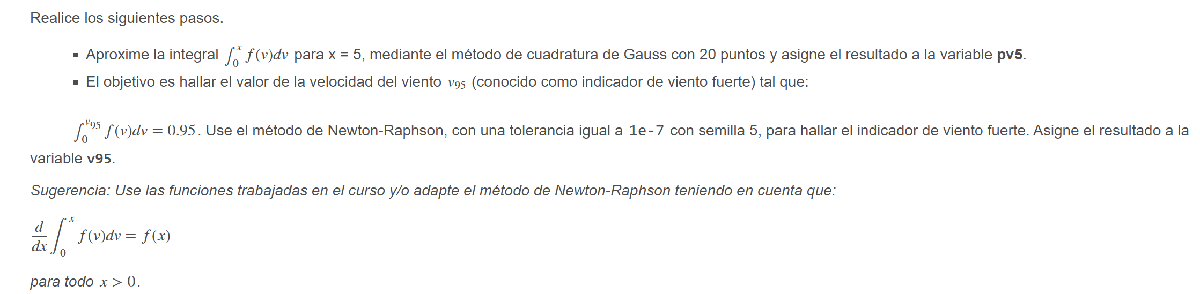

format long

k = 3.5;
c = 4.2;

syms v

f_sym = (k/c) * (v/c)^(k-1) * exp(-(v/c)^k);

f = matlabFunction(f_sym)

a = 0;
b = 5;
n = 20;
pv5 = gaussnp(f, a, b, n);

tol = 1e-7;
v0 = 5;

F = @(v) gaussnp(f, 0, v, n) - 0.95;

F_sym = int(f_sym, 0, v) - 0.95;

F_deriv_sym = diff(F_sym, v);

F_deriv = matlabFunction(F_deriv_sym, 'Vars', v);

z_values = newton(F, v0, tol, F_deriv); 

v95 = z_values(end)


%{

f = function_handle with value:
    @(x)1/(sqrt(2*pi))*exp(-x.^(2)/2)


t =    0.000014867195147   2.659620158407934   0.656571045608754   0.989535883373848   1.002213544581077
   1.994718835604737   0.781761615158702   0.984333307783769   1.002164022466986                   0
   1.085000920270211   0.971672576994702   1.001885417550061                   0                   0
   1.000004662813579   0.999997115015351                   0                   0                   0
   0.999999001964908                   0                   0                   0                   0


r =    1.002213544581077


int1 =    1.002213544581077


int2 =    1.185719616013499


f = function_handle with value:
    @(v)exp(-(v.*(5.0./2.1e+1)).^(7.0./2.0)).*(v.*(5.0./2.1e+1)).^(5.0./2.0).*(5.0./6.0)


v95 =    5.746362287545644


function G=gaussnp(f,a,b,n)
%Version de alumno José Daniel Rodas Núñez
syms x
%PRIMER PASO: Calcular el polinomio de Legendre de grado n
lg=legendreP(n,x);
dlg=matlabFunction(diff(lg,x));
%SEGUNDO PASO: Calcular las raíces del polinomio de Legendre
roots=double(vpasolve(lg==0));
%TERCER PASO: Calcular los pesos de las raíces del polinomio de Legendre
pesos=(2./((1-roots.^2).*dlg(roots).^2));
%CUARTO PASO: Transformar los límites de la fxn
syms t
x=((b-a)*t+(a+b))/2;
F=matlabFunction(f(x));
%QUINTO PASO: Calcular el valor de la integral
G=((b-a)/2)*sum(pesos.*(F(roots)));
end

function z=newton(f, x0, Tol, df)
    z = x0;
    error = 1;
    while error > Tol
        x1 = x0 - f(x0) / df(x0);
        z = [z; x1];
        error = abs(x1 - x0) / abs(x1);
        x0=x1;
    end
end
%}

P4

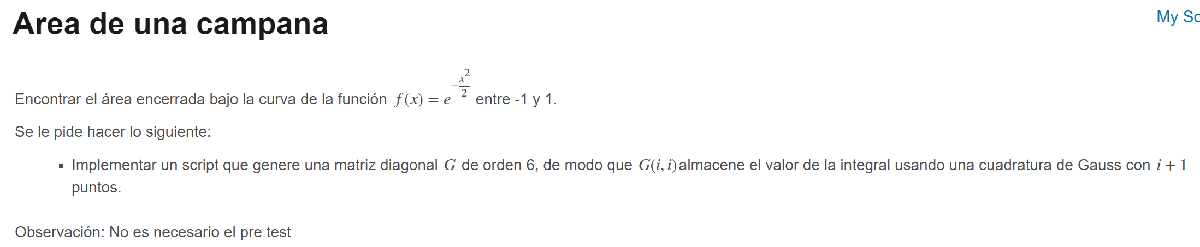

% Configura la precisión numérica en formato largo
format long 

syms x
f_sym = exp(-x^2 / 2);

f = matlabFunction(f_sym, 'Vars', x);

n = 6;

G = zeros(n, n);

for i = 1:n
    
    [nodes, weights] = lgwt(i+1, -1, 1);
    
    integral_value = sum(weights .* f(nodes));
    
    G(i, i) = integral_value;
end

G

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FUNCIÓN PARA OBTENER NODOS Y PESOS DE GAUSS-LEGENDRE (use esta variacion propuesta por De la Fuente O'Connor)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%{

G =    1.692963449781228                   0                   0                   0                   0                   0
                   0   1.712020245201907                   0                   0                   0                   0
                   0                   0   1.711224504599491                   0                   0                   0
                   0                   0                   0   1.711249393524465                   0                   0
                   0                   0                   0                   0   1.711248771041351                   0
                   0                   0                   0                   0                   0   1.711248784012376


function [x, w] = lgwt(N, a, b)
% Calcula los N nodos y pesos de Gauss-Legendre en el intervalo [a, b].
% Código auxiliar para el cálculo de integrales definidas mediante cuadratura de Gauss.
% Si se desea calcular la integral de f(x) en este intervalo,
% se debe evaluar f(x) en los puntos del vector x y calcular la suma ponderada con w:
% Integral aproximada = sum(f(x) .* w).

% Ajusta N para que coincida con el grado del polinomio de Legendre
N = N - 1; 
N1 = N + 1; 
N2 = N + 2; 

% Genera una distribución inicial de puntos en [-1,1]
xu = linspace(-1, 1, N1)'; 

% Aproximación inicial de los ceros del polinomio de Legendre
y = cos((2*(0:N)' + 1) * pi / (2*N + 2)) + (0.27/N1) * sin(pi * xu * N / N2); 

% Matrices para almacenar los polinomios de Legendre y sus derivadas
L = zeros(N1, N2);  % Matriz de polinomios de Legendre
Lp = zeros(N1, N2); % Matriz de derivadas de los polinomios de Legendre

% Iteración para encontrar los ceros del polinomio de Legendre (método de Newton-Raphson)
y0 = 2; % Valor inicial arbitrario para la comparación en el bucle
while max(abs(y - y0)) > eps % Criterio de convergencia basado en la tolerancia numérica (eps)
    % Inicializa los primeros dos polinomios de Legendre
    L(:,1) = 1;  % P_0(x) = 1
    Lp(:,1) = 0; % Derivada de P_0(x)

    L(:,2) = y;  % P_1(x) = x
    Lp(:,2) = 1; % Derivada de P_1(x) = 1

    % Calcula los polinomios de Legendre usando la relación de recurrencia
    for k = 2:N1
        L(:,k+1) = ((2*k-1) * y .* L(:,k) - (k-1) * L(:,k-1)) / k; 
    end

    % Calcula las derivadas de los polinomios de Legendre evaluados en y
    Lp = (N2) * (L(:,N1) - y .* L(:,N2)) ./ (1 - y.^2); 

    % Aplica el método de Newton-Raphson para refinar las raíces del polinomio de Legendre
    y0 = y; 
    y = y0 - L(:,N2) ./ Lp; 
end

% Transforma los nodos de [-1,1] a [a,b]
x = (a * (1 - y) + b * (1 + y)) / 2; 

% Calcula los pesos de la cuadratura de Gauss-Legendre
w = (b - a) ./ ((1 - y.^2) .* Lp.^2) * (N2 / N1)^2; 
end
%}

P5

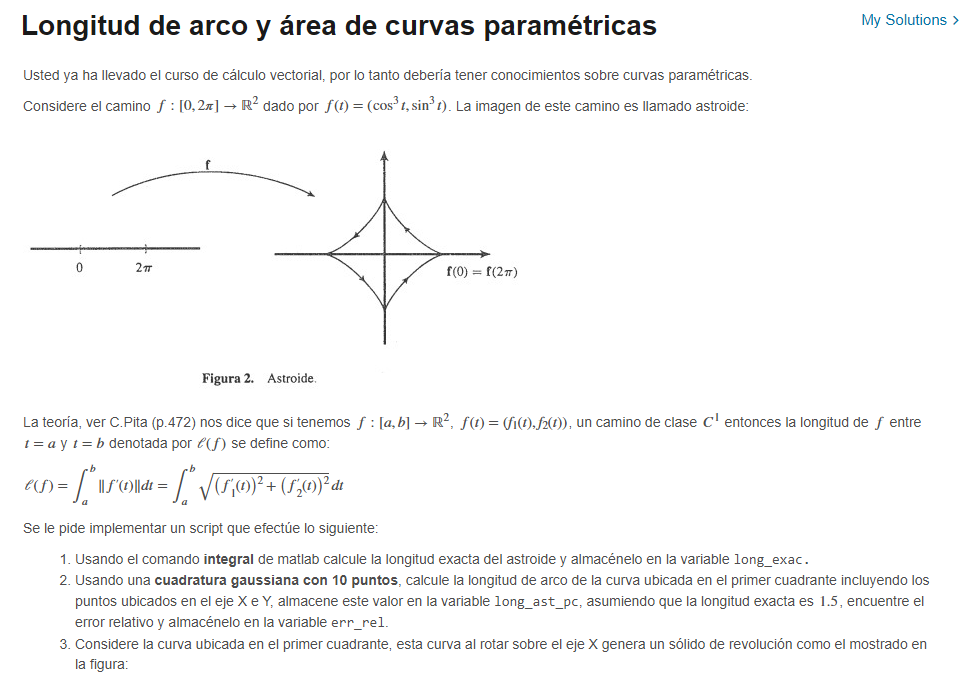

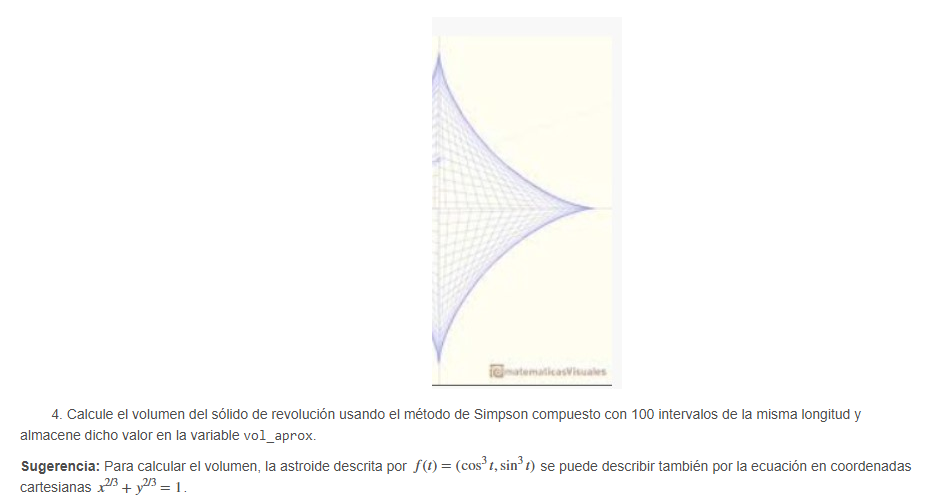

format long



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PARAMETRIZACIÓN DE LA CURVA
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Se define la parametrización de la curva en el plano
syms t
f1 = @(t) cos(t).^3; % Coordenada x en función de t
f2 = @(t) sin(t).^3; % Coordenada y en función de t

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CÁLCULO DE LA LONGITUD DE LA CURVA EXACTA
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Se define la función de la norma de la derivada del vector de posición
df1 = diff(f1, t);
df2 = diff(f2, t);
f_norm = sqrt(df1^2 + df2^2);

% Límites de integración para la curva parametrizada
a = 0; 
b = 2 * pi;

% Se calcula la longitud exacta de la curva mediante integración simbólica
f_norm_func = matlabFunction(f_norm, 'Vars', t);
long_exac = integral(f_norm_func, a, b);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CÁLCULO DE LA LONGITUD DE LA CURVA APROXIMADA
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Número de puntos en la cuadratura de Gauss
n = 10; 

% Se calcula una aproximación de la longitud de la curva con cuadratura de Gauss

a_quadrant = 0;
b_quadrant = pi/2;

long_ast_pc = gaussnp(f_norm_func, a_quadrant, b_quadrant, n);
% Se calcula el error relativo con respecto a un valor de referencia (1.5)
long_exact_quadrant = 1.5;
err_rel = abs(long_ast_pc - long_exact_quadrant) / long_exact_quadrant;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CÁLCULO DEL VOLUMEN DE ROTACIÓN
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Se redefine la variable simbólica
syms x

% Se define la función a rotar alrededor del eje x
f2_rot = (1 - x.^(2/3)).^(3/2);

% Límites de integración
a = 0; 
b = 1;

% Cálculo exacto del volumen mediante integración simbólica
vol_exac = pi * int(f2_rot^2, x, 0, 1);

% Número de subdivisiones para el método de Simpson
n = 100;

% Cálculo aproximado del volumen usando la regla de Simpson compuesta
vol_aprox = simpsoncomp(matlabFunction(pi * f2_rot.^2, 'Vars', x), a, b, n);

%{
function G = gaussnp(f, a, b, n)
    syms x

    % PRIMER PASO: Calcular el polinomio de Legendre de grado n
    lg = legendreP(n, x);
    
    % Se obtiene la derivada del polinomio de Legendre
    dlg = matlabFunction(diff(lg, x));

    % SEGUNDO PASO: Calcular las raíces del polinomio de Legendre
    roots = double(vpasolve(lg == 0));

    % TERCER PASO: Calcular los pesos asociados a las raíces del polinomio de Legendre
    pesos = (2 ./ ((1 - roots.^2) .* dlg(roots).^2));

    % CUARTO PASO: Transformar los límites de integración al intervalo [-1,1]
    syms t
    x = ((b - a) * t + (a + b)) / 2;

    % Se define la función transformada para el nuevo intervalo
    F = matlabFunction(f(x));

    % QUINTO PASO: Calcular la integral como suma ponderada de la función en los nodos
    G = ((b - a) / 2) * sum(pesos .* (F(roots)));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FUNCIÓN PARA INTEGRACIÓN POR LA REGLA DE SIMPSON COMPUESTA
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function I = simpsoncomp(f, a, b, n)
    % Se calcula el tamaño del subintervalo
    h = (b - a) / n; 
    
    % Se generan los puntos de la partición
    xp = [a:h:b]; 
    
    % Se evalúa la función en estos puntos
    yp = f(xp); 
    
    % Se extraen los valores de la función en los nodos impares y pares
    ypimpar = yp(2:2:n);
    yppar = yp(3:2:n-1);

    % Aplicación de la regla de Simpson compuesta
    I = (h / 3) * (f(a) + 4 * sum(ypimpar) + 2 * sum(yppar)+f(b));
end

%}


P6

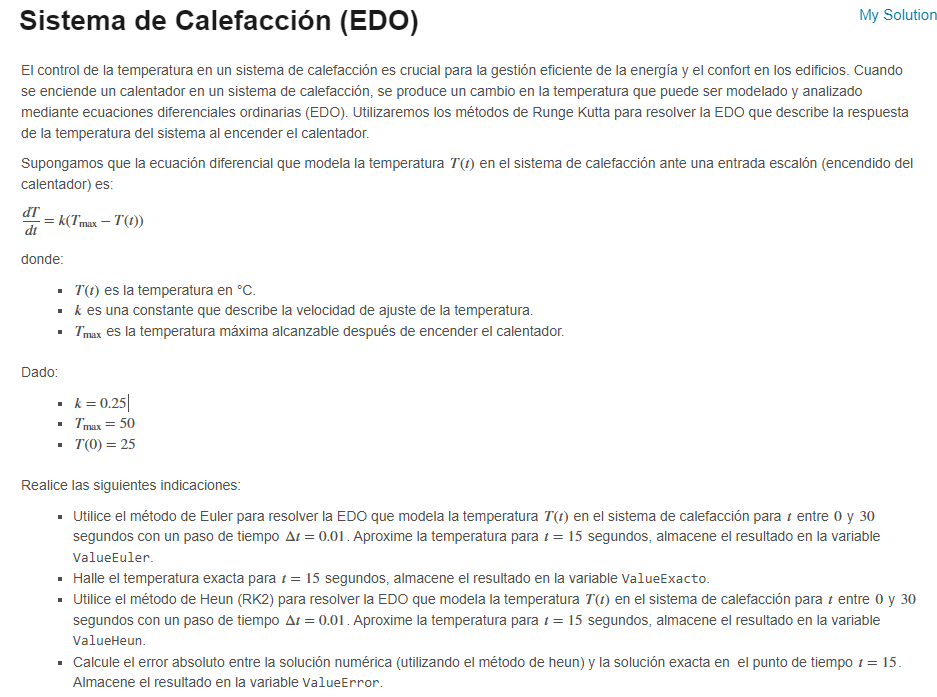

format long
%Datos:
k=0.25;
T0=25;
a=0;
b=30;
h=0.01;
Tmax=50;
t_find = 15;
%Definiendo la función f(t,Q)
f = @(t, T) k * (Tmax - T);
%{
%Método de Euler
euler_result = euler(f, a, b, T0, h);

[ab, idx] = min(abs(euler_result(:,1) - t_find));
ValueEuler = euler_result(idx, 2);

%Solución Exacta
T_exact = @(t) Tmax - (Tmax - T0) * exp(-k * t)
ValueExacto = T_exact(t_find)

%Método de Heun

heun_result = rk2(f, a, b, T0, h);
% Extraemos el valor de la temperatura en t=15
[bc, idx] = min(abs(heun_result(:,1) - t_find));
ValueHeun = heun_result(idx, 2);


%Error absoluto

ValueError = abs(ValueHeun - ValueExacto)
%}
%{
%Funciones
function z=euler(f,a,b,y0,h)
t=[a:h:b];
n=length(t);
z=[t(1) y0];
for k=1:n-1
    y1=y0+h*f(t(k),y0);
    z=[z;t(k+1) y1];
    y0=y1;
end
end

function z=rk2(f,a,b,y0,h)
t=[a:h:b];
n=length(t);
z=[t(1) y0];
for k=1:n-1
    k1=f(t(k),y0);
    k2=f(t(k)+h,y0+h*k1);
    y1=y0+(h/2)*(k1+k2);
    z=[z;t(k+1) y1];
  y0=y1;
end
end
%}

P7

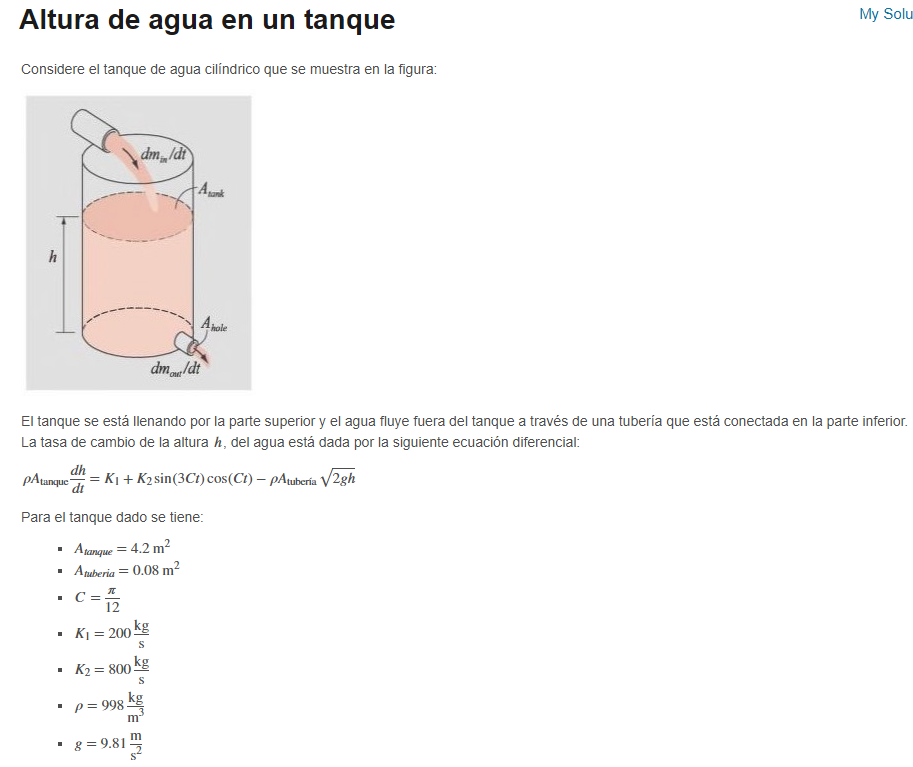

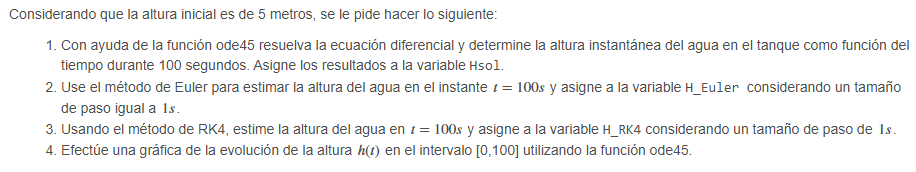

format long
%Hsol es una matriz que tiene dos columnas en la primera al tiempo y en la segunda la altura que trabaja en un paso por defecto de la propia funcion

Atanque = 4.2;
Atuberia = 0.08;
C = pi / 12;
K1 = 200;
K2 = 800;
rho = 998;
g = 9.81;
h0 = 5;
tspan = [0 100];
dt = 1;

dhdt = @(t, h) (K1 + K2 * sin(3 * C * t) * cos(C * t) - rho * Atuberia * sqrt(2 * g * h)) / (rho * Atanque);

[t_ode, h_ode] = ode45(dhdt, tspan, h0);
Hsol = [t_ode, h_ode];

[ab, H_Eul] = euler(dhdt,0, 100, h0, 1)

H_Euler = H_Eul(end)

[bc, H_RK4] = rk4(dhdt,0, 100, h0, 1)

H_RK4 = H_RK4(end)
% graficando
figure;
plot(Hsol(:,1), Hsol(:,2), 'b', 'LineWidth', 1.5); %completar en lugar de []
xlabel('Time (seconds)');
ylabel('Height (m)');
title('Water Height in Tank vs Time');
grid on;


%{
function [tt2,y_euler] = euler(f,ti, tf,y0,h)
tt2 = ti:h:tf; tt2 = tt2';
y_euler = zeros(size(tt2));
y_euler(1,1) = y0;
for i=1:length(tt2)-1
    y_euler(i+1,1) = y_euler(i,1) + h*f(tt2(i,1),y_euler(i,1));
end
end


function [tt2,y_rk4] = rk4(f,ti, tf,y0,h)
tt2 = ti:h:tf; tt2 = tt2';
y_rk4 = zeros(size(tt2));
y_rk4(1,1) = y0;
for i=1:length(tt2)-1
    k1 = f(tt2(i,1),y_rk4(i,1));
    k2 = f(tt2(i,1) + 0.5*h, y_rk4(i,1) + 0.5*h*k1);
    k3 = f(tt2(i,1) + 0.5*h, y_rk4(i,1) + 0.5*h*k2);
    k4 = f(tt2(i,1) + h, y_rk4(i,1) + h*k3);
    y_rk4(i+1,1) = y_rk4(i,1) + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
end
end
%}

P8

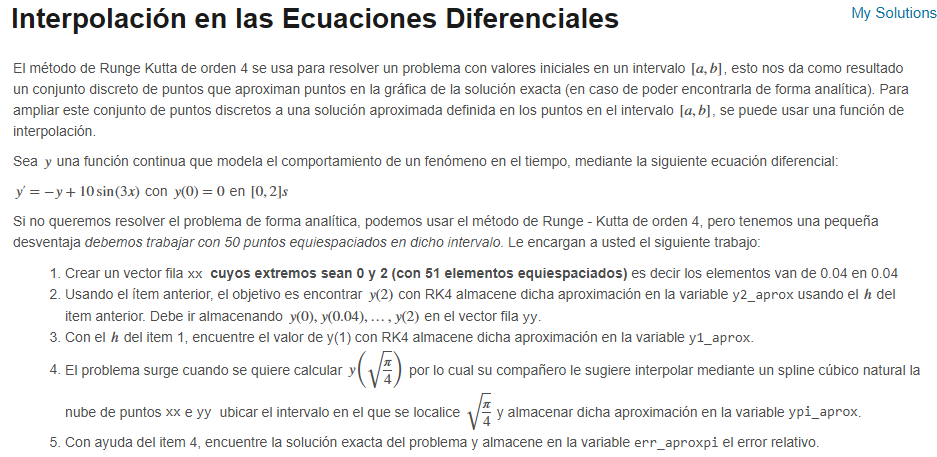

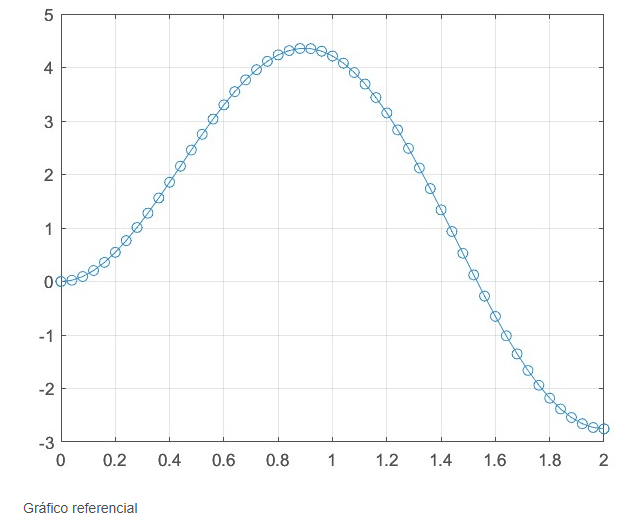

format long
% Definir la función de la ecuación diferencial
f = @(t, y) -y + 10 * sin(3 * t);

% Parámetros del problema
tspan = [0, 2]; % Intervalo de tiempo
y0 = 0; % Condición inicial
N = 50; % Número de pasos

% Resolver la ecuación diferencial con RK4
[t, y] = runge_kutta_order4(f, tspan, y0, N);

% Definir variables xx y yy
xx = t; % Vector de tiempos donde se evaluó la aproximación
yy = y; % Valores aproximados obtenidos con RK4

% Asegurar que xx y yy sean valores numéricos
xx = double(xx);
yy = double(yy);

% Encontrar y(1) y y(2) usando RK4
[~, idx1] = min(abs(xx - 1));
y1_aprox = yy(idx1);

[~, idx2] = min(abs(xx - 2));
y2_aprox = yy(idx2);

% Interpolación cúbica natural con spline
S = splinenatural(xx, yy);

% Evaluar la interpolación en el punto solicitado sqrt(pi/4)
t_eval = sqrt(pi / 4);
ypi_aprox = interp1(xx, yy, t_eval, 'spline')

% Calcular la solución exacta en el punto solicitado
syms y_exact(t_sym)
ode = diff(y_exact) + y_exact == 10 * sin(3 * t_sym);
cond = y_exact(0) == 0;
sol_exact = dsolve(ode, cond);
sol_exact_eval = double(subs(sol_exact, t_sym, t_eval));

% Calcular el error relativo
err_aproxpi = abs((sol_exact_eval - ypi_aprox) / sol_exact_eval)

% Mostrar los resultados
fprintf('Aproximación de y(1) con RK4: %f\n', y1_aprox);
fprintf('Aproximación de y(2) con RK4: %f\n', y2_aprox);
fprintf('Interpolación cúbica en sqrt(pi/4) (ypi_aprox): %f\n', ypi_aprox);
fprintf('Solución exacta en sqrt(pi/4): %f\n', sol_exact_eval);
fprintf('Error relativo (err_aproxpi): %f\n', err_aproxpi);

% Graficar la solución de RK4 y la interpolación spline
figure;
plot(xx, yy, 'o', 'MarkerSize', 5, 'DisplayName', 'Solución RK4');
hold on;
t_fine = linspace(0, 2, 200);
yy_spline = interp1(xx, yy, t_fine, 'spline');
plot(t_fine, yy_spline, '-', 'DisplayName', 'Interpolación Spline');
xline(t_eval, 'r--', 'DisplayName', 'x = sqrt(pi/4)');
scatter(t_eval, ypi_aprox, 'ro', 'DisplayName', sprintf('Interpolado en %.3f', t_eval));
legend;
xlabel('t');
ylabel('y');
title('Solución de la EDO e Interpolación');
grid on;
hold off;

%%funciones a utilizar

function [t, y] = runge_kutta_order4(f, tspan, y0, N)
% f es la función de la ecuación diferencial dy/dt = f(t, y)
% tspan es el intervalo de tiempo [t0, tf]
% y0 es la condición inicial y(t0) = y0
% N es el número de pasos
t0 = tspan(1);
tf = tspan(2);
h = (tf - t0) / N; % tamaño del paso
t = t0:h:tf; % vector de tiempo
y = zeros(1, N+1); % vector para almacenar los valores de y
y(1) = y0; % asignamos la condición inicial
for i = 1:N
k1 = h * f(t(i), y(i));
k2 = h * f(t(i) + h/2, y(i) + k1/2);
k3 = h * f(t(i) + h/2, y(i) + k2/2);
k4 = h * f(t(i) + h, y(i) + k3);
y(i+1) = y(i) + (k1 + 2*k2 + 2*k3 + k4) / 6;
end
end


function S=splinenatural(X,Y)
N=length(X)-1; H=diff(X); E=diff(Y)./H;
diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1);
g0=0; gn=0;
A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
b=6*diff(E'); g=A\b;
g=[g0 g' gn];
for i=1:N
S(i,1)=(g(i+1)-g(i))/(6*H(i));
S(i,2)=g(i)/2;
S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
S(i,4)=Y(i);
xx=linspace(X(i),X(i+1),100);
yy=S(i,1)* (xx-X(i)).^3+S(i,2)* (xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
plot(xx,yy), hold on
end
grid on,hold off
end


P9

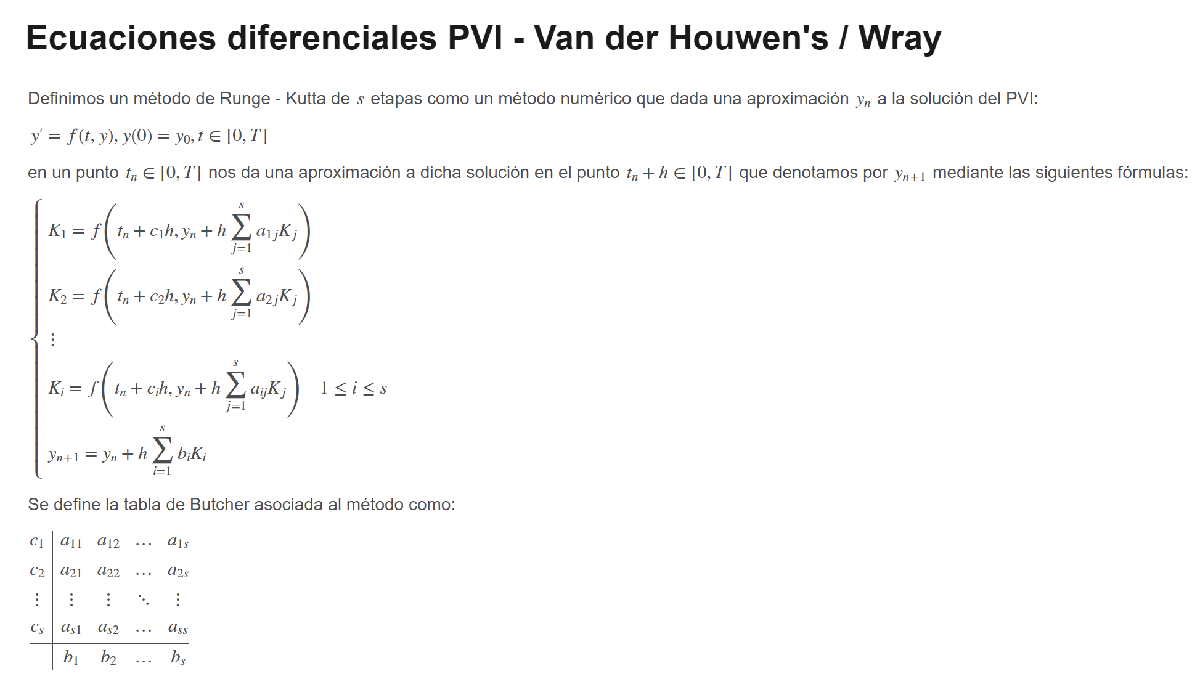

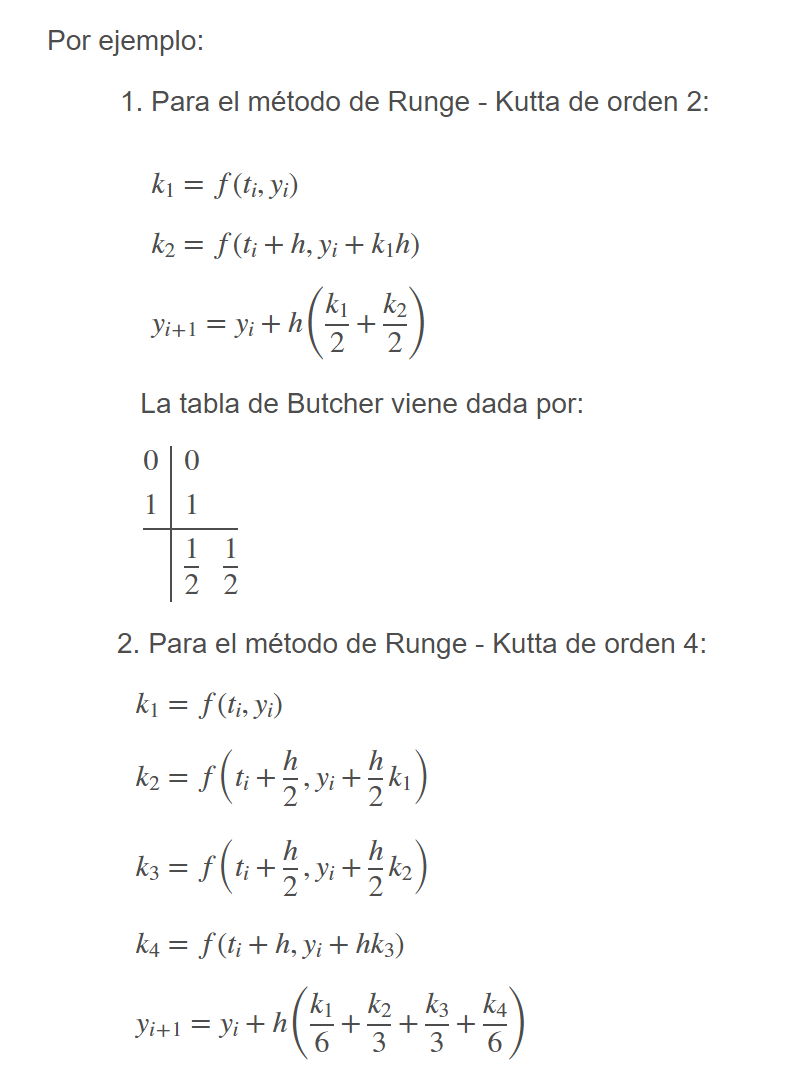

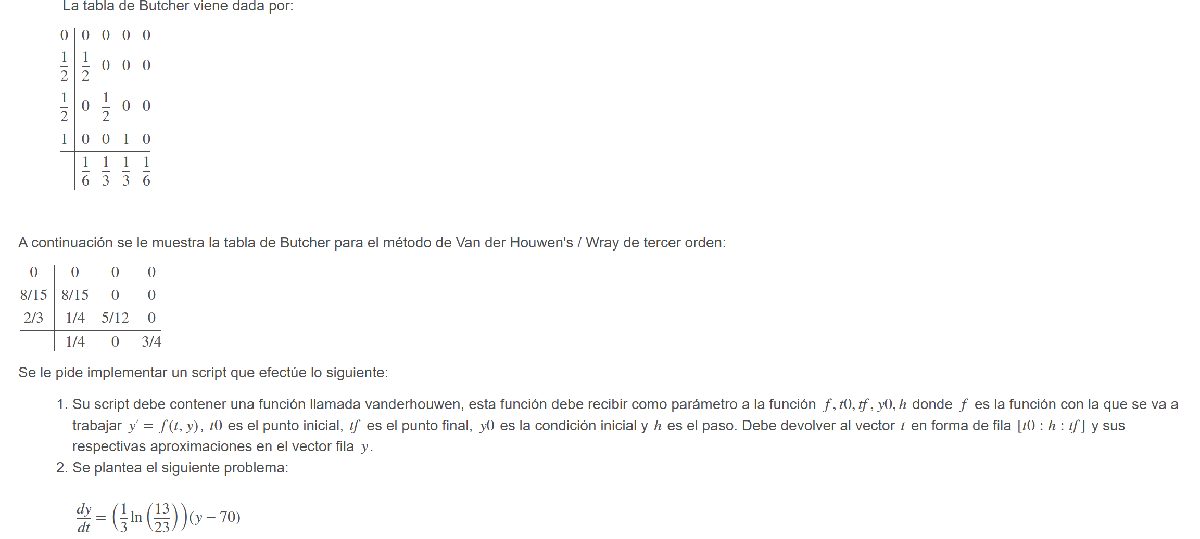

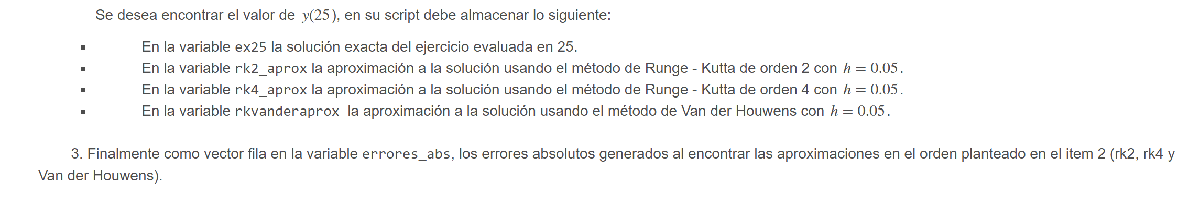

format long
syms y(x)
y0 = 300;

% Definir la ecuación diferencial
f = (1/3)*log(13/23)*(y - 70);
ode = diff(y, x) == f;

% Resolver la ecuación diferencial exactamente
sol = dsolve(ode, y(0) == y0);
sol = simplify(sol);

% Evaluar la solución exacta en x = 25
ex25 = double(subs(sol, x, 25))

% Definir la función para métodos numéricos
f_num = @(x, y) (1/3)*log(13/23)*(y - 70);

% Método ode45
[x1, y1] = ode45(f_num, [0 25], y0);

% Método Runge-Kutta de segundo orden
z1 = rk2(f_num, 0, 25, y0, 0.05);
rk2_aprox = z1(end, 2)

% Método Runge-Kutta de cuarto orden
[x2, y2] = runge_kutta_order4(f_num, [0 25], y0, 500);
rk4_aprox = y2(end)

% Método Van der Houwen
van = vanderouwen(f_num, 0, 25, y0, 0.05);
rkvanderaprox = van(end)

% Cálculo de errores absolutos
errores_abs = [abs(ex25 - rk2_aprox), abs(ex25 - rk4_aprox), abs(ex25 - rkvanderaprox)]

% Funciones auxiliares

%{
function y = vanderouwen(f, t0, tf, y0, h)
    t = t0:h:tf;
    y = zeros(size(t));
    y(1) = y0;
    for i = 1:length(t)-1
        k1 = f(t(i), y(i));
        k2 = f(t(i) + h/2, y(i) + h*k1/2);
        k3 = f(t(i) + h/2, y(i) + h*k2/2);
        k4 = f(t(i) + h, y(i) + h*k3);
        y(i+1) = y(i) + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
    end
end

function z = rk2(f, a, b, y0, h)
    t = a:h:b;
    n = length(t);
    z = [t(1) y0];
    for k = 1:n-1
        k1 = f(t(k), y0);
        k2 = f(t(k) + h, y0 + h*k1);
        y1 = y0 + (h/2)*(k1 + k2);
        z = [z; t(k+1) y1];
        y0 = y1;
    end
end

function [t, y] = runge_kutta_order4(f, tspan, y0, N)
    t0 = tspan(1);
    tf = tspan(2);
    h = (tf - t0) / N;
    t = t0:h:tf;
    y = zeros(1, N+1);
    y(1) = y0;
    for i = 1:N
        k1 = h * f(t(i), y(i));
        k2 = h * f(t(i) + h/2, y(i) + k1/2);
        k3 = h * f(t(i) + h/2, y(i) + k2/2);
        k4 = h * f(t(i) + h, y(i) + k3);
        y(i+1) = y(i) + (k1 + 2*k2 + 2*k3 + k4)/6;
    end
end
%}

P10

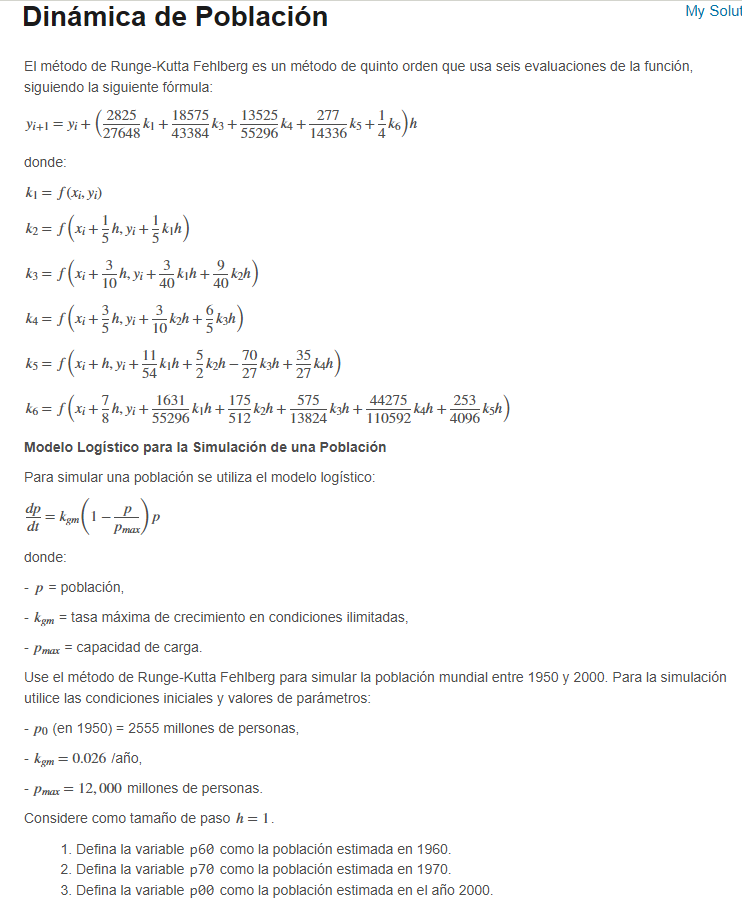

format long

p0 = 2555;
kgm = 0.026;
pmax = 12000;
h = 1;
f = @(t,p) kgm * (1 - p / pmax) * p;
[T, P] = Runge_Kutta_Fehlberg(f, [0 50], p0, h);
p60 = P(11)
p70 = P(21)
p00 = P(51)
function [T, Y] = Runge_Kutta_Fehlberg(f, tspan, y0, h)
t0 = tspan(1);
tf = tspan(2);
T = t0:h:tf;
d = length(y0);
N = floor((tf - t0) / h);
Y = zeros(d, N+1);
Y(:,1) = y0;
for i = 1:N
 xi = T(i);
 yi = Y(:, i);
 k1 = f(xi , yi);
 k2 = f(xi + 1/5*h , yi + h * k1 * 1/5);
 k3 = f(xi + 3/10*h , yi + h * (k1 * 3/40 + k2 * 9/40));
 k4 = f(xi + 3/5*h , yi + h * (k2 * 3/10 + k3 * 6/5));
 k5 = f(xi + h , yi + h * (k1 * 11/54 + k2 * 5/2 - k3 * 70/27 + 35/27 * k4));
 k6 = f(xi + 7/8*h , yi + h * (k1 * 1631/55296 + k2 * 175/512 - k3 * 575/13824 + k4 * 44275/110592 - k5 * 253/4096 ));
 y_next = yi + h * (k1 * 2825/27648 + k3 * 18575/43384 + k4 * 13525/55296 + k5 * 277/14336 + k6 * 1/4);
 Y(:, i+1) = y_next;
end
end

Funciones

ab =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


H_Eul =    5.000000000000000
   4.859056487781116
   4.851149369147216
   4.878323055375368
   4.835118167296471
   4.697311358619036
   4.527238032286333
   4.395434979405699
   4.301193827312863
   4.173929797510134


H_Euler =    0.515808110863824


bc =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


H_RK4 =    5.000000000000000
   4.929929016122517
   4.948073792940854
   4.944747625634686
   4.851138327603860
   4.690069360416461
   4.535477450792710
   4.425828439267629
   4.321497417473295
   4.149870399600489


H_RK4 =    0.510736010244070


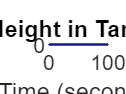

% Función que calcula la integral mediante la cuadratura de Gauss


function [Igauss] = QuadraturaGauss(f, a, b, n)
    % Matriz de coeficientes de pesos de Gauss-Legendre para diferentes órdenes (n=2,3,4,5)
    coef = [1 1 0 0 0; 
            0.5555556 0.8888889 0.5555556 0 0; 
            0.3478548 0.6521452 0.6521452 0.3478548 0; 
            0.2369269 0.4786287 0.5688889 0.4786287 0.2369269]; 

    % Matriz de nodos de Gauss-Legendre para diferentes órdenes (n=2,3,4,5)
    nodos = [-0.577350269  0.577350269  0  0  0; 
             -0.774596669  0  0.774596669  0  0; 
             -0.861136312 -0.339981044  0.339981044  0.861136312  0; 
             -0.906179846 -0.538469310  0  0.538469310  0.906179846]; 

    % Función de transformación para cambiar de dominio [-1,1] a [a,b]
    g = @(x) ((b + a) / 2 + (b - a) * x / 2); 

    % Inicializa la variable de la integral
    I = 0; 

    % Suma los valores de la función evaluada en los nodos ponderados por los coeficientes
    for i = 1:n
        I = I + coef(n-1,i) * f(g(nodos(n-1,i))); 
    end

    % Multiplica por el factor de cambio de variable (b-a)/2
    I = (b-a) * I / 2; 

    % Retorna el resultado de la cuadratura de Gauss
    Igauss = I; 
end

function [T, R] = romberg(fun, a, b, orden)
    interv = 1; % Número inicial de intervalos

    % Calcula la primera columna de la tabla de Romberg usando la regla del trapecio compuesta
    for j = 1:orden
        T(j,1) = Tcomp(fun, a, b, interv); 
        interv = interv * 2; % Duplica el número de intervalos en cada paso
    end

    % Completa la tabla de Romberg usando extrapolación de Richardson
    for k = 2:orden
        for j = 1:(orden-k+1)
            T(j,k) = (4^(k-1) * T(j+1,k-1) - T(j,k-1)) / (4^(k-1) - 1); 
        end
    end

    % La mejor aproximación está en la esquina superior derecha de la tabla
    R = T(1,orden); 
end

function [Itrapcomp] = Tcomp(f, a, b, n)
    % Calcula el tamaño de los subintervalos
    h = (b - a) / n; 

    % Genera los puntos de la partición
    x = [a:h:b]; 

    % Aplica la regla del trapecio compuesta
    Itrapcomp = (h/2) * (f(a) + 2 * sum(f(x(2:length(x)-1))) + f(b)); 
end
function S = splinenatural(X,Y)
    % Número de intervalos
    N = length(X) - 1; 
    
    % Diferencias entre los puntos
    H = diff(X); 
    E = diff(Y) ./ H;
    
    % Construcción de la matriz del sistema
    diagprinc = 2 * (H(1:N-1) + H(2:N)); 
    diagsupinf = H(2:N-1);
    
    % Condiciones de frontera
    g0 = 0; 
    gn = 0;
    
    % Matriz A y vector b
    A = diag(diagprinc) + diag(diagsupinf, 1) + diag(diagsupinf, -1);
    b = 6 * diff(E'); 
    g = A \ b;
    g = [g0; g; gn];
    
    % Coeficientes del spline
    S = zeros(N, 4);
    for i = 1:N
        S(i,1) = (g(i+1) - g(i)) / (6 * H(i));
        S(i,2) = g(i) / 2;
        S(i,3) = E(i) - H(i) * (g(i+1) + 2 * g(i)) / 6;
        S(i,4) = Y(i);
    end
end
function val = evalSpline(X, S, x)
    i = find(X <= x, 1, 'last'); % Encontrar el intervalo correcto
    if i == length(X), i = i - 1; end % Si x está en el último nodo, ajustamos
    dx = x - X(i);
    val = S(i,1)*dx^3 + S(i,2)*dx^2 + S(i,3)*dx + S(i,4);
end
function G=gaussnp(f,a,b,n)
%Version de alumno José Daniel Rodas Núñez
syms x
%PRIMER PASO: Calcular el polinomio de Legendre de grado n
lg=legendreP(n,x);
dlg=matlabFunction(diff(lg,x));
%SEGUNDO PASO: Calcular las raíces del polinomio de Legendre
roots=double(vpasolve(lg==0));
%TERCER PASO: Calcular los pesos de las raíces del polinomio de Legendre
pesos=(2./((1-roots.^2).*dlg(roots).^2));
%CUARTO PASO: Transformar los límites de la fxn
syms t
x=((b-a)*t+(a+b))/2;
F=matlabFunction(f(x));
%QUINTO PASO: Calcular el valor de la integral
G=((b-a)/2)*sum(pesos.*(F(roots)));
end

function z=newton(f, x0, Tol, df)
    z = x0;
    error = 1;
    while error > Tol
        x1 = x0 - f(x0) / df(x0);
        z = [z; x1];
        error = abs(x1 - x0) / abs(x1);
        x0=x1;
    end
end

function [x, w] = lgwt(N, a, b)
% Calcula los N nodos y pesos de Gauss-Legendre en el intervalo [a, b].
% Código auxiliar para el cálculo de integrales definidas mediante cuadratura de Gauss.
% Si se desea calcular la integral de f(x) en este intervalo,
% se debe evaluar f(x) en los puntos del vector x y calcular la suma ponderada con w:
% Integral aproximada = sum(f(x) .* w).

% Ajusta N para que coincida con el grado del polinomio de Legendre
N = N - 1; 
N1 = N + 1; 
N2 = N + 2; 

% Genera una distribución inicial de puntos en [-1,1]
xu = linspace(-1, 1, N1)'; 

% Aproximación inicial de los ceros del polinomio de Legendre
y = cos((2*(0:N)' + 1) * pi / (2*N + 2)) + (0.27/N1) * sin(pi * xu * N / N2); 

% Matrices para almacenar los polinomios de Legendre y sus derivadas
L = zeros(N1, N2);  % Matriz de polinomios de Legendre
Lp = zeros(N1, N2); % Matriz de derivadas de los polinomios de Legendre

% Iteración para encontrar los ceros del polinomio de Legendre (método de Newton-Raphson)
y0 = 2; % Valor inicial arbitrario para la comparación en el bucle
while max(abs(y - y0)) > eps % Criterio de convergencia basado en la tolerancia numérica (eps)
    % Inicializa los primeros dos polinomios de Legendre
    L(:,1) = 1;  % P_0(x) = 1
    Lp(:,1) = 0; % Derivada de P_0(x)

    L(:,2) = y;  % P_1(x) = x
    Lp(:,2) = 1; % Derivada de P_1(x) = 1

    % Calcula los polinomios de Legendre usando la relación de recurrencia
    for k = 2:N1
        L(:,k+1) = ((2*k-1) * y .* L(:,k) - (k-1) * L(:,k-1)) / k; 
    end

    % Calcula las derivadas de los polinomios de Legendre evaluados en y
    Lp = (N2) * (L(:,N1) - y .* L(:,N2)) ./ (1 - y.^2); 

    % Aplica el método de Newton-Raphson para refinar las raíces del polinomio de Legendre
    y0 = y; 
    y = y0 - L(:,N2) ./ Lp; 
end

% Transforma los nodos de [-1,1] a [a,b]
x = (a * (1 - y) + b * (1 + y)) / 2; 

% Calcula los pesos de la cuadratura de Gauss-Legendre
w = (b - a) ./ ((1 - y.^2) .* Lp.^2) * (N2 / N1)^2; 
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FUNCIÓN PARA INTEGRACIÓN POR LA REGLA DE SIMPSON COMPUESTA
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function I = simpsoncomp(f, a, b, n)
    % Se calcula el tamaño del subintervalo
    h = (b - a) / n; 
    
    % Se generan los puntos de la partición
    xp = [a:h:b]; 
    
    % Se evalúa la función en estos puntos
    yp = f(xp); 
    
    % Se extraen los valores de la función en los nodos impares y pares
    ypimpar = yp(2:2:n);
    yppar = yp(3:2:n-1);

    % Aplicación de la regla de Simpson compuesta
    I = (h / 3) * (f(a) + 4 * sum(ypimpar) + 2 * sum(yppar)+f(b));
end

function z=rk2(f,a,b,y0,h)
t=[a:h:b];
n=length(t);
z=[t(1) y0];
for k=1:n-1
    k1=f(t(k),y0);
    k2=f(t(k)+h,y0+h*k1);
    y1=y0+(h/2)*(k1+k2);
    z=[z;t(k+1) y1];
    y0=y1;
end
end

%{
function z=euler(f,a,b,y0,h)
t=[a:h:b];
n=length(t);
z=[t(1) y0];
for k=1:n-1
    y1=y0+h*f(t(k),y0);
    z=[z;t(k+1) y1];
    y0=y1;
end
end
%}
function [tt2,y_euler] = euler(f,ti, tf,y0,h)
tt2 = ti:h:tf; tt2 = tt2';
y_euler = zeros(size(tt2));
y_euler(1,1) = y0;
for i=1:length(tt2)-1
    y_euler(i+1,1) = y_euler(i,1) + h*f(tt2(i,1),y_euler(i,1));
end
end


function [tt2,y_rk4] = rk4(f,ti, tf,y0,h)
tt2 = ti:h:tf; tt2 = tt2';
y_rk4 = zeros(size(tt2));
y_rk4(1,1) = y0;
for i=1:length(tt2)-1
    k1 = f(tt2(i,1),y_rk4(i,1));
    k2 = f(tt2(i,1) + 0.5*h, y_rk4(i,1) + 0.5*h*k1);
    k3 = f(tt2(i,1) + 0.5*h, y_rk4(i,1) + 0.5*h*k2);
    k4 = f(tt2(i,1) + h, y_rk4(i,1) + h*k3);
    y_rk4(i+1,1) = y_rk4(i,1) + (h/6)*(k1 + 2*k2 + 2*k3+k4);
end
end

function y = vanderouwen(f, t0, tf, y0, h)
    t = t0:h:tf;
    y = zeros(size(t));
    y(1) = y0;
    for i = 1:length(t)-1
        k1 = f(t(i), y(i));
        k2 = f(t(i) + h/2, y(i) + h*k1/2);
        k3 = f(t(i) + h/2, y(i) + h*k2/2);
        k4 = f(t(i) + h, y(i) + h*k3);
        y(i+1) = y(i) + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
    end
end